##  МИУ

close all;
clear variables;

Входные параметры

%  1 - входные данные 
k0 = 2*pi;
% Параметры среды-1
e1 = 2.56;
mu1 = 1;
k1 = k0*sqrt(mu1*e1);
eta1 = 120*pi*sqrt(mu1/e1);

% Параметры среды-2
k2 = k0;
eta2 = 120*pi;

% Параметры программы
N = 600; % количество точек на круга
% полуоси элипса
a = 2; 
b = 1;
phi_i_grad = 0; % угол падения [град]
phi_i_rad = 2*pi/360*phi_i_grad; % угол падения [рад]
gamma = 1.781072417990;

% ========================================================================
%  Построение круга
dphi_grad = 360/N; % угловой шаг на круга [град]
dphi_rad =  2*pi/360*dphi_grad; % угловой шаг на круга [рад]


Генерация точек

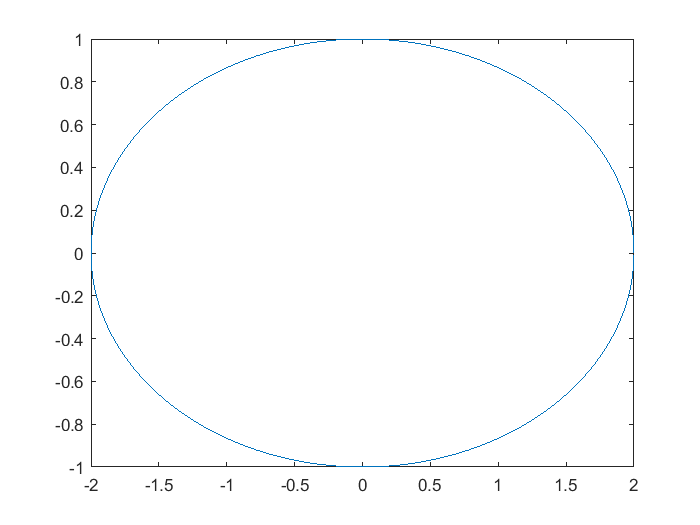

dphi_grad = 360/N;
x = zeros(1,N);
z = zeros(1,N);

for i = 1 : N
    z(i) = b*sind(dphi_grad*(i-1));
    x(i) = a*cosd(dphi_grad*(i-1));
end

plot(x,z)

Расчет dx для каждого участка

for i = 1 : N
    if i == N
        d_x = (x(1)-x(i));
        d_z = (z(1)-z(i));
    else
        d_x = (x(i+1)-x(i));
        d_z = (z(i+1)-z(i));
    end
    
    dx_mass(i) = sqrt(d_x^2+d_z^2);    
end

Посчитаем t для каждого отрезка

for i = 1 : N
    dx = dx_mass(i);
    if i == N
        tx(i) = -((x(1)-x(i)))/dx;
        tz(i) = -((z(1)-z(i)))/dx;
    else
        tx(i) = -(x(i+1)-x(i))/dx;
        tz(i) = -(z(i+1)-z(i))/dx;
    end
end

Посчитаем n для каждого отрезка

%  Посчитаем n для каждого отрезка
%  нормальный вектор найдем с помощью матрицы повороты
    alpha = -90;
    matrix = [cosd(alpha),-sind(alpha); sind(alpha),cosd(alpha)];

for i = 1 : N
     matrix_temp = [tx(i), tz(i)]*matrix;
     nx(i) = matrix_temp(1);
     nz(i) = matrix_temp(2);
end

Координаты центров отрезков

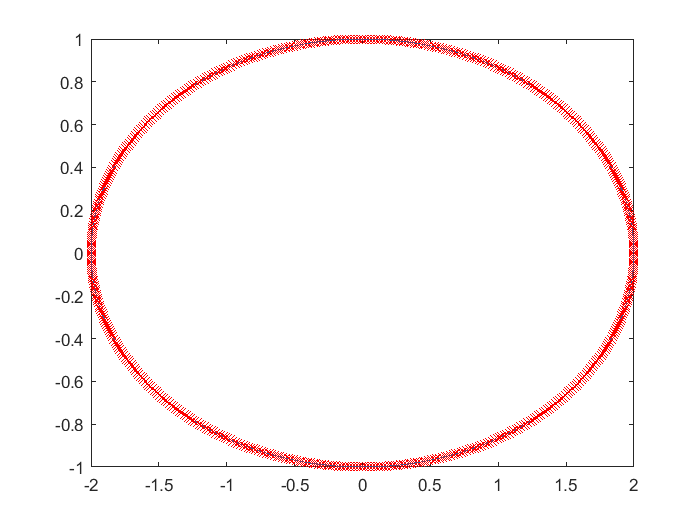

for i = 1 : N 
    if i == N
        x_midle(i) = ((x(1)+x(i)))/2;
        z_midle(i) = ((z(1)+z(i)))/2;
    else
        x_midle(i) = (x(i+1)+x(i))/2;
        z_midle(i) = (z(i+1)+z(i))/2;
    end    
end

plot(x,z,x_midle, z_midle, 'rx');

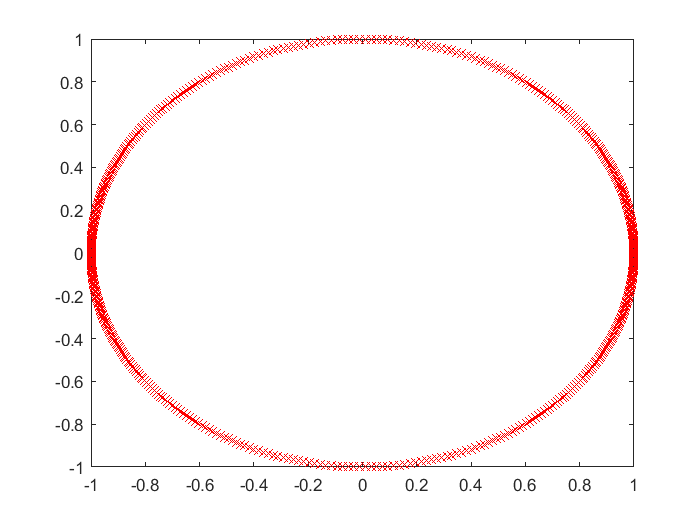


% визуализируем tx и tz
plot(tx, tz, 'rx');

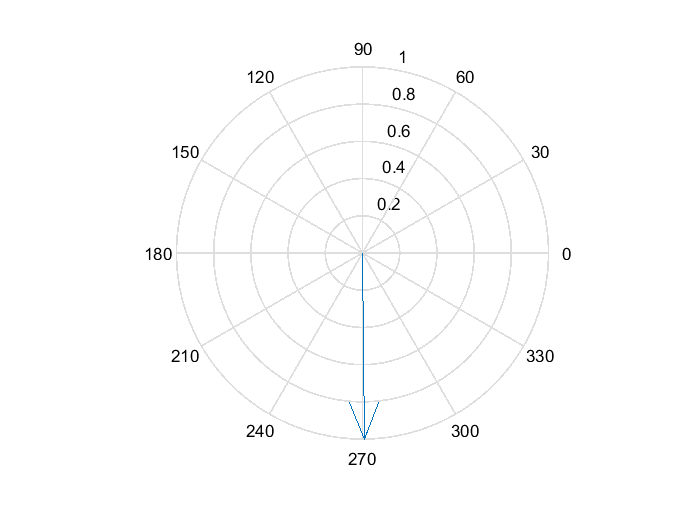

compass(tx(1),tz(1));


% ========================================================================
% 3 - cам ходя расчета 
% списик для хранения элементов системы 
Z = zeros(2*N,2*N);
Y = zeros(2*N,2*N);
    
for m  = 1 : N
    xm = x_midle(m);
    zm = z_midle(m);
    txm = tx(m);
    tzm = tz(m);
    nxm = nx(m);
    nzm = nz(m);
    
    for n = 1 : N
        xn = x_midle(n);
        zn = z_midle(n);
        txn = tx(n);
        tzn = tz(n);
        nxn = nx(n);
        nzn = nz(n);
        dx = dx_mass(n);
        
        % Растояние между началом координат О2 и точкой наблюдений (в ГСК)        
        x_mO2 = xm - xn;
        z_mO2 = zm - zn;
        
        % Положим этот вектор на новую СК
        % Координаты этой точки (в ЛСК)
        umn = x_mO2*txn + z_mO2*tzn;
        wmn = x_mO2*nxn + z_mO2*nzn;
        
        
        % локальные замены 
        xmn = xm - xn;
        zmn = zm - zn;
        r = sqrt(xmn^2 + zmn^2);
        
        umn_plus = umn + dx/2;
        umn_minus = umn - dx/2; 
        r_minus = sqrt(umn_minus^2 + wmn^2);
        r_plus = sqrt(umn_plus^2 + wmn^2);
        rmn = sqrt(umn^2 + wmn^2);
        
        if n == m
            % электрическое поле
            E1u = + 1/2;
            E2u = - 1/2;
            E1w = 0;
            E2w = 0;
            
            
            % магнитное поле
            H1y = - k1/eta1*dx*1/4*(1 + 1i*2/pi*(log(gamma*k1*dx/4)-1));
            H2y = - k2/eta2*dx*1/4*(1 + 1i*2/pi*(log(gamma*k2*dx/4)-1));

        elseif abs(n-m) <= 1.5
        
            % электрчиеское поле
            E1u = - (1i/8*wmn*k1^2*dx + 1/(2*pi)*(atan(umn_plus/wmn) - atan(umn_minus/wmn)));
            E2u = - (1i/8*wmn*k2^2*dx + 1/(2*pi)*(atan(umn_plus/wmn) - atan(umn_minus/wmn)));
            E1w = - 1i/4*(H(0,k1*r_plus) - H(0,k1*r_minus));
            E2w = - 1i/4*(H(0,k2*r_plus) - H(0,k2*r_minus));
            
            % магнитное поле 
            H1y = k1*dx + k1*2*1i/pi * (wmn*(atan(umn_plus/wmn) - atan(umn_minus/wmn))...
            + umn_plus*log(gamma*k1/2*sqrt(umn_plus^2+wmn^2))...
            - umn_minus*log(gamma*k1/2*sqrt(umn_minus^2+wmn^2)) - dx);
            H1y = - H1y * 1/eta1 * 1/4;
            
            H2y = k2*dx + k2*2*1i/pi * (wmn*(atan(umn_plus/wmn) - atan(umn_minus/wmn))...
            + umn_plus*log(gamma*k2/2*sqrt(umn_plus^2+wmn^2))...
            - umn_minus*log(gamma*k2/2*sqrt(umn_minus^2+wmn^2)) - dx);
            H2y = - H2y * 1/eta2 * 1/4;
            
        else
            % электрчиеское поле
            E1u = - 1i/4*k1*dx*(wmn/rmn*H(1,k1*rmn));
            E2u = - 1i/4*k2*dx*(wmn/rmn*H(1,k2*rmn));
            E1w = - 1i/4*(H(0,k1*r_plus) - H(0,k1*r_minus));
            E2w = - 1i/4*(H(0,k2*r_plus) - H(0,k2*r_minus));
               
            % магнитное поле  
            H1y = -k1/eta1*1/4*dx*H(0,k1*rmn);
            H2y = -k2/eta2*1/4*dx*H(0,k2*rmn);
        end
        % элементы системы       
        H1mn = H1y;
        H2mn = -H2y;
        
        dot_tm_tn = (txm*txn+tzm*tzn);
        dot_tm_nn = (txm*nxn+tzm*nzn);
        
        E1mn = dot_tm_tn*E1u + dot_tm_nn*E1w;
        E2mn = -(dot_tm_tn*E2u + dot_tm_nn*E2w);
        
        % запись в массив для дальнешего решения 
        Z(m,n) = E1mn;
        Z(m,n+N) = E2mn;
        Z(m+N,n) = H1mn;
        Z(m+N,n+N) = H2mn;
    end
end

E = zeros(2*N,1);
% падающее поле 
for m = 1 : N
    xm = x_midle(m);
    zm = z_midle(m);
    txm = tx(m);
    tzm = tz(m);

    % cоставляющие полей
    cx = -1i*k2*cosd(phi_i_grad);
    cz = -1i*k2*sind(phi_i_grad);
    
    Hiy = exp(cx*xm+cz*zm);
    Eix = - eta2*sind(phi_i_grad) * Hiy;
    Eiz = + eta2*cosd(phi_i_grad) * Hiy;
    
    % элементы системы  
    Hi = Hiy;
    Ei = txm*Eix + tzm*Eiz;

    % запись в массив для дальнешего решения 
    E(m) = Ei;
    E(m+N) = Hi;
end     

% Расчитаем токи
% тут зашито сразу 2 тока
I = Z\E;

% отделим один ток от другого
j1 = I(1:N);
j2 = I(N+1:2*N);

Сделаем счетчик для графика в градусах

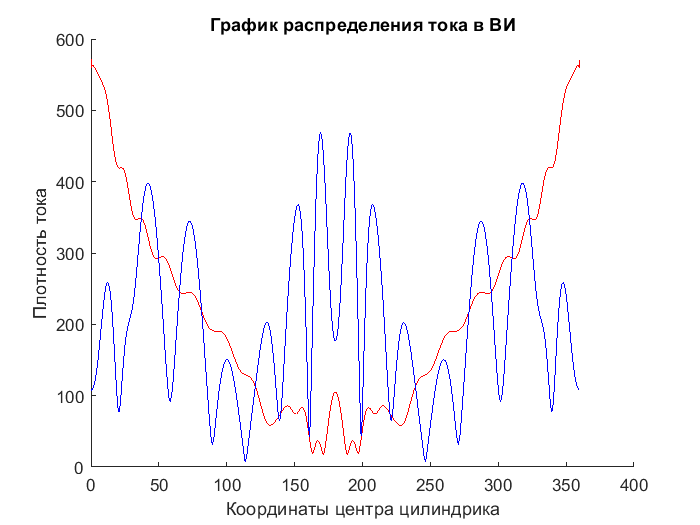

for i = 1 : N
    z_m = z_midle(i);
    x_m = x_midle(i);
    
    if (x_m <= 0 && z_m < 0) || (x_m >= 0 && z_m < 0)
        phi_for_graf_real(i) = atan2(z_m, x_m)*180/pi+360;
    else
        phi_for_graf_real(i) = atan2(z_m, x_m)*180/pi;
    end
end

figure;
hold on;
plot(phi_for_graf_real, abs(j1), 'r');
plot(phi_for_graf_real, abs(j2), 'b');
title('График распределения тока в ВИ'); 
xlabel('Координаты центра цилиндрика'); 
ylabel('Плотность тока');
hold off;

Полярные графики

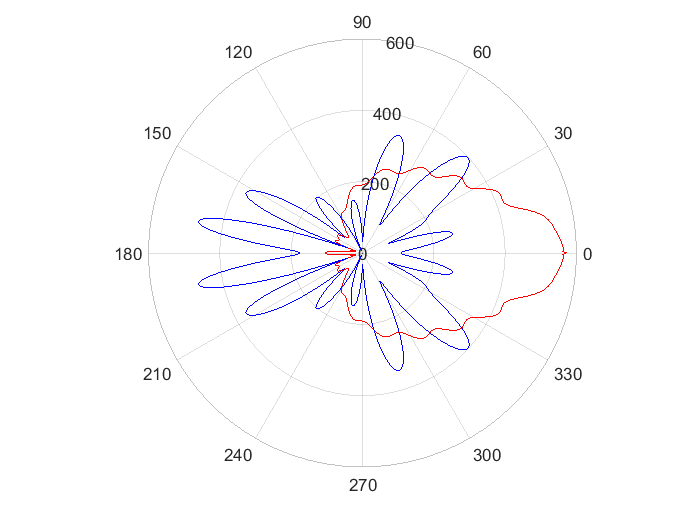

% полярный графки токов
polarplot(deg2rad(phi_for_graf_real), abs(j1), 'r',deg2rad(phi_for_graf_real), abs(j2), 'b');

### Магнитное Поле на поврехности 

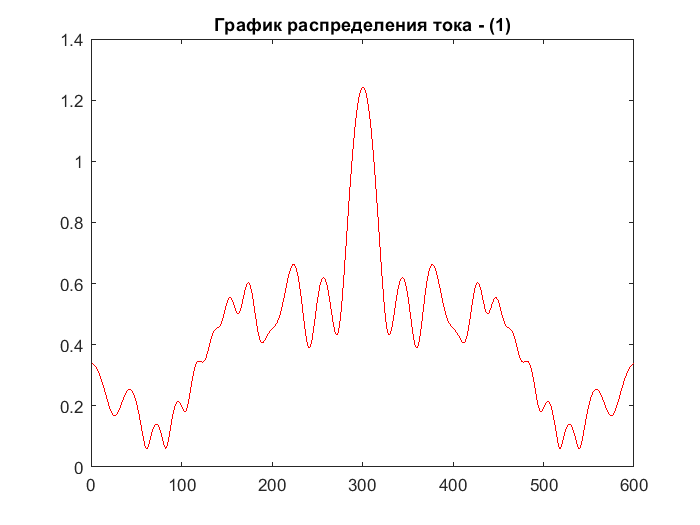

E_surf = zeros(N, 1); 
for m  = 1 : N
    xm = x_midle(m);
    zm = z_midle(m);
    txm = tx(m);
    tzm = tz(m);
    nxm = nx(m);
    nzm = nz(m);
    n_for_graf(m) = m; % для графика
    
    
    H_surf_n = 0;
    for n = 1 : N
        xn = x_midle(n);
        zn = z_midle(n);
        txn = tx(n);
        tzn = tz(n);
        nxn = nx(n);
        nzn = nz(n);
        dx = dx_mass(n);
            
        % Растояние между началом координат О2 и точкой наблюдений (в ГСК)        
        x_mO2 = xm - xn;
        z_mO2 = zm - zn;
        
        % Положим этот вектор на новую СК
        % Координаты этой точки (в ЛСК)
        umn = x_mO2*txn + z_mO2*tzn;
        wmn = x_mO2*nxn + z_mO2*nzn;
        
        % локальные замены 
        xmn = xm - xn;
        zmn = zm - zn;
        r = sqrt(xmn^2 + zmn^2);
        
        umn_plus = umn + dx/2;
        umn_minus = umn - dx/2; 
        r_minus = sqrt(umn_minus^2 + wmn^2);
        r_plus = sqrt(umn_plus^2 + wmn^2);
        rmn = sqrt(umn^2 + wmn^2);   
        
        if n == m
            % электрическое поле
            H2y = - k2/eta2*dx*1/4*(1 + 1i*2/pi*(log(gamma*k2*dx/4)-1));
              
        elseif abs(n-m) <= -1.5
            % электрчиеское поле
            H2y = k2*dx + k2*2*1i/pi * (wmn*(atan(umn_plus/wmn) - atan(umn_minus/wmn))...
            + umn_plus*log(gamma*k2/2*sqrt(umn_plus^2+wmn^2))...
            - umn_minus*log(gamma*k2/2*sqrt(umn_minus^2+wmn^2)) - dx);
            H2y = - H2y * 1/eta2 * 1/4;

        else
            % электрчиеское поле
            H2y = -k2/eta2*1/4*dx*H(0,k2*rmn);
        end
        
        H_surf_n = H_surf_n + j2(n) * H2y;
    end
    
    H_surf(m) =  H_surf_n; 
 end
 
figure;
plot(n_for_graf, abs(H_surf), 'r');
title('График распределения тока - (1)'); 

## ЭПР

for p = 1 : 721
    Sum_E = 0;
    phi = (p-1)/2; % угол из формулы для приведения 721 к 360 градусам
    phi_for_graf_DA(p) = (p-1)/2; % угол для графика
    
    cx = - 1i*k2*cosd(phi);
    cz = - 1i*k2*sind(phi);
    

        for n = 1 : N
            txn = tx(n);
            tzn = tz(n);
            xn = x_midle(n);
            zn = z_midle(n);
            dx = dx_mass(n);
            
            Sum_E = Sum_E + 1/eta2*k2/4*dx*j2(n)*exp(cx*xn+cz*zn);      
        end
    
    RCS(p) = 10*log10((4/k2)*Sum_E*conj(Sum_E));

end

% график поля в дальней зоне от угла налюденя (не нормированный)
figure;
plot(phi_for_graf_DA, RCS,'r-');

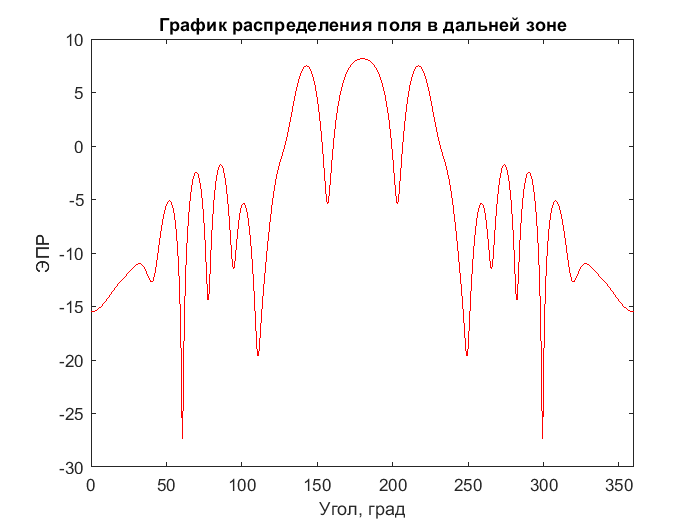

title('График распределения поля в дальней зоне'); 
xlim([0 360])
xlabel('Угол, град'); 
ylabel('ЭПР');

### Вывод данных для графиков

% name_file = strcat('I_MIE_elips_diel_Hpol_j1_', num2str(N),'.dat');
% f01 = fopen(name_file,'w');
% 
% % за максимум Y примем значения в центре передней стороны падения
% 
% for n=1:N
%     fprintf(f01,' %10.5f %10.5f\n', phi_for_graf_real(n), abs(j1(n)));
% end
% 
% fclose(f01);

% name_file = strcat('I_MIE_elips_diel_Hpol_j2_', num2str(N),'.dat');
% f02 = fopen(name_file,'w');
% 
% % за максимум Y примем значения в центре передней стороны падения
% 
% for n=1:N
%     fprintf(f02,' %10.5f %10.5f\n', phi_for_graf_real(n), abs(j2(n)));
% end
% 
% fclose(f02);

% name_file = strcat('Hsurf_MIE_elips_diel_Hpol_j2_', num2str(N),'.dat');
% f04 = fopen(name_file,'w');
% 
% % за максимум Y примем значения в центре передней стороны падения
% 
% for n= 1 : N
%     fprintf(f04,' %10.5f %10.5f\n', phi_for_graf_real(n), abs(H_surf(n)));
% end
% 
% fclose(f04);

% name_file = strcat('DA_MIE_elips_diel_Hpol_j2_', num2str(N),'.dat');
% f03 = fopen(name_file,'w');
% 
% % за максимум Y примем значения в центре передней стороны падения
% 
% for n= 1 : 721
%     fprintf(f03,' %10.5f %10.5f\n', phi_for_graf_DA(n), RCS(n));
% end
% 
% fclose(f03);

function [H_calc] = H(n,x)
    H_calc = besselh(n,1,x); 
end

function [J_calc] = J(n,x)
    J_calc = besselJ(n,x); 
end
    
function [dJ_calc] = dJ(n,x)
    dJ_calc = n/x*besselj(n,x) - besselj(n+1,x);
end

function [dH_calc] = dH(n,x)
    dH_calc = n/x*besselh(n,1,x) - besselh(n+1,1,x);
end